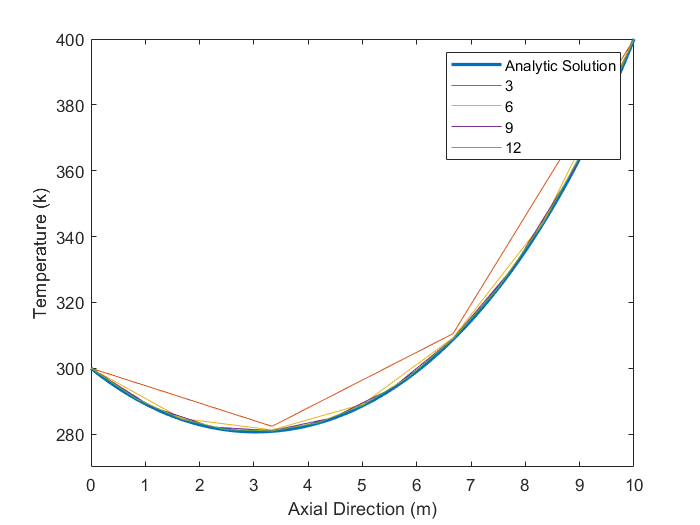

clear

h = 0.05;
T_constant = 200;
T_0 = 300;
T_10 = 400;

f = linspace(0,20,100000);
real_T = 200 + 20.4671*exp(f*sqrt(0.05)) + 79.5329*exp(-sqrt(0.05)*f);

plot(f, real_T, "LineWidth", 2)
legend {Analytic Solution}
ylabel('Temperature (k)')
xlabel('Axial Direction (m)')
ylim ([270 400])
xlim ([0 10])
hold on    

for n = 3:3:12
    delta_x = 10/n;
    x = 0:delta_x:10;
    v = zeros(1, n-2);
    y = zeros(1, n-1);
    v(:,:) = 1/(delta_x)^2;
    y(:,:) = -((2/(delta_x)^2) + h);
    A = diag(v, -1) + diag(y) + diag(v, 1);
    b = zeros(n-1, 1);
    b(1,:) = -(1/(delta_x)^2)*T_0 - h*T_constant;
    b(end,:) = -(1/(delta_x)^2)*T_10 - h*T_constant;
    b(2:end-1,:) = -h*T_constant;
    b = b;
    T_x = mldivide(A,b);
    T_x = [300;T_x;400];
    
    plot(x, T_x, 'DisplayName', num2str(n))
    hold on
end


